# This MATLAB live script provides details of modeling and analysis of the benchmark **10-bar truss **optimization problems.

**By: **Mohammad Farshchin, Ph.D.

**Email: **Mohammad.Farshchin@gmail.com

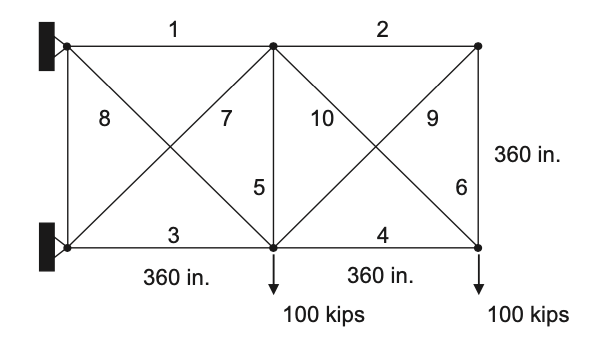

### **For detailed information about this benchmark problem refer to the following paper:**

- Camp, C.V. & Farshchin, M. (2014). [Design of space trusses using modified teaching-learning based optimization](http://www.sciencedirect.com/science/article/pii/S0141029614000236), Engineering Structures 62-63, 87-97

### **Please also refer to the following publications for information about several optimization algorithms to optimize this problems:**

- Farshchin, M., Maniat, M., Camp, C.V., & Pezeshk, S. (2018). [School based optimization algorithm for design of steel frames](https://www.sciencedirect.com/science/article/pii/S0141029617308787), Engineering Structures, Volume 171, 326-335.

- Farshchin, M., Camp, C.V., & Maniat, M. (2016). [Multi-class teaching–learning-based optimization for truss design with frequency constraints](http://www.sciencedirect.com/science/article/pii/S0141029615006732), Engineering Structures, Volume 106, 1, 355-369.

- Farshchin, M., Camp, C.V., & Maniat, M. (2016). [Optimal design of truss structures for size and shape with frequency constraints using a collaborative optimization strategy](https://www.sciencedirect.com/science/article/pii/S0957417416304900), Expert Systems with Applications, Vol 66.

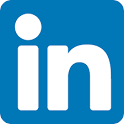 [https://www.linkedin.com/in/mfarshchin/](https://www.linkedin.com/in/mfarshchin/)          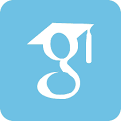 [https://scholar.google.com/citations?user=ZYO6CwEAAAAJ&hl=en](https://scholar.google.com/citations?user=ZYO6CwEAAAAJ&hl=en)

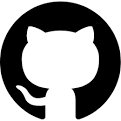 [https://github.com/mfarshchin](https://github.com/mfarshchin)                         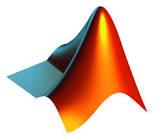 [https://www.mathworks.com/matlabcentral/profile/authors/3727592-mohammad-farshchin](https://www.mathworks.com/matlabcentral/profile/authors/3727592-mohammad-farshchin)

## Benchmark 1: 10-bar truss problem with *continuous* design variables

Configuration of the 10-bar benchmark truss is shown in the figure above. For additional details please refere to [this](http://www.sciencedirect.com/science/article/pii/S0141029614000236) publication.

**Main scripts for modeling and analysis:** 

- **Data10.m  **Properties of 10-bar truss (e.g. geometry, loading, boundary conditions, penalty function, etc) are defined here 

- **ST10.m** This function is to run the analysis for a design

The following set of commands are to run the 10-bar truss for a randomly generated design

D=Data10; % Define the truss
Design=[33, 1.5, 23, 14.1, 1.5, 1.5, 23, 8, 1.5, 22]; % Define a random design 
% Analyze the design and compte the total weight of truss (Weight, lbs) and objective value (penalized weight) 
[Weight,Objective]=ST10(Design,D);
% print the design
fprintf('Truss Design is: \n\n'),disp(Design)

Truss Design is: 

   33.0000    1.5000   23.0000   14.1000    1.5000    1.5000   23.0000    8.0000    1.5000   22.0000



fprintf('Truss weight is: %6.4f lbs\n',Weight);

Truss weight is: 5460.2870 lbs


fprintf('Penalized weight (Objective value) is: %6.4f\n',Objective);

Penalized weight (Objective value) is: 5466.0221


Note: for details of panalty function check out the Data10.m file

## Benchmark 2: 10-bar truss problem with *discrete* design variables

Configuration of the 10-bar benchmark truss is shown in the figure above. For additional details please refere to [this](http://www.sciencedirect.com/science/article/pii/S0141029614000236) publication.

Note: Since this benchmark problem is a discrete optimization algorithm, an extra step is requred to map the continuous design variables (generated by optimization) to the available discrete design variables. For more clarification see the following code.

**Main scripts for modeling and analysis:** 

- **Data10.m  **Properties of 10-bar truss (e.g. geometry, loading, boundary conditions, penalty function, etc) are defined here 

- **ST10.m** This function is to run the analysis for a design (discrete design)

The following set of commands are to run the 10-bar truss for a randomly generated design

D=Data10; % Define the truss
% Define a rnadom design with discrete variables
ConDesign=[33, 1.5, 23, 14.1, 1.5, 1.5, 23, 8, 1.5, 22];
fprintf('Truss Design with continuous variables is: \n'),disp(ConDesign)

Truss Design with continuous variables is: 
   33.0000    1.5000   23.0000   14.1000    1.5000    1.5000   23.0000    8.0000    1.5000   22.0000



Now we map this design with continuous variables to a viable design with discrete design vairables. For this purpose, we replace each continuous design varible with the closest available discrete design variable.

for I=1:size(ConDesign,2)
    [~,b]=min(abs(D.AV-ConDesign(1,I))); %D.AV contains available sections (See Data10.m)
    DisDesign(1,I)=D.AV(b);
end
fprintf('Truss Design with discrete variables is: \n'),disp(DisDesign)

Truss Design with discrete variables is: 
   33.5000    1.6200   22.9000   14.2000    1.6200    1.6200   22.9000    7.9700    1.6200   22.0000



Now we can perform analysis for this design

% Analyze the design and compte the total weight of truss (Weight, lbs) and objective value (penalized weight) 
[Weight,Objective]=ST10(DisDesign,D);
% print the results
fprintf('Truss weight is: %6.4f lbs\n',Weight);

Truss weight is: 5490.7379 lbs


fprintf('Penalized weight (Objective value) is: %6.4f\n',Objective);

Penalized weight (Objective value) is: 5490.7379
